# Paddle Model

***Note that running the MATLAB Live Script requires version > R2016a.***

***Run paddlemodel.m instead if your MATLAB version does not support Live Scripts.***

***Also note that sign definition of L and BK and inverted from nonlinobserver.m.***

% parameters
m = 0.1; % mass of ball, kg
M = 1.0; % mass of paddle, kg
g = 9.8; % gravitational constant, m/s^2
l = 1.0; % length of paddle, m
%paddlemodel(m,M,g,l);

%function paddlemodel(m,M,g,l)

% prepare figure
clc
figure(1);clf;
subplot 221;hold on
subplot 223;hold on
subplot 122;hold on
subplot 122; plot(0,0,'+', 'DisplayName', 'origin', 'MarkerSize', 12, 'LineWidth', 3, 'MarkerEdgeColor', 'k')

% roll parameters
params = [m M g l];

% system definition
A = [
    0,0,1,0;
    0,0,0,1;
    0,-g,0,0;
    -12*g*m/(l^2*M),0,0,0];
B = [0;0;0;12/(l^2*M)];
C = [1,0,0,0;0,1,0,0];
D = 0;

plant = ss(A,B,C,D);

% sim definition
t=0:.1:6;
tspan=[0 20];

x0=[
    0.0 0.0 0.0 0.0;
    0.1 0.0 0.0 0.0;
    0.0 -deg2rad(10.0) 0.0 0.0;
    -0.2 deg2rad(20.0) 0.0 0.0;
    0.3 deg2rad(30.0) 0.0 0.0;
    ]';

x0 = x0(:,4);
subplot 122; plot(-0.2,deg2rad(20.0),'x', 'DisplayName', 'initial', 'MarkerSize', 12, 'LineWidth', 2, 'MarkerEdgeColor', 'k')

%"good" estimate
%est = x0;

% "bad" estimate (@ 0)
% est = zeros(size(x0));

% "okay" estimate
est = x0 * 0.2;

x0_err = (x0 - est) ;
x0_hat = [x0; x0_err];
n_test = size(x0, 2);

% commented out, for axis limits.
% for i=1:2,
%     [~,t,x]=lsim(plant,zeros(size(t)),t,x0(:,i));
%     subplot 221;plot(t,x(:,1),'g--','DisplayName','lin plant')
%     subplot 223;plot(t,x(:,2),'g--','DisplayName','lin plant')
%     subplot 122;plot(x(:,1),x(:,2),'g--','DisplayName','lin plant')
% end

## Controller

% lqr ...
Q = diag([1.0,1.0,0.0,0.0]);
R = 0.2;
[Kfull,~,~] = lqr(A,B,Q,R);
%Kfull = -Kfull;

% pole placement ...
s1 = -1 / 0.05;
s2 = -1 / 0.08;
s3 = -1 / 1.0;
s4 = -1 / 1.2;

k1 = m*g + l^2*M*s1*s2*s3*s4/(12*g);
k2 = -1/12*l^2*M*(s3*s4+s2*(s3+s4)+s1*(s2+s3+s4));
k3 = -l^2*M*(s1*s2*s3+s2*s3*s4+s1*(s2+s3)*s4)/(12*g);
k4 = 1/12*l^2*M*(s1+s2+s3+s4);

Kpole = -[k1 k2 k3 k4];

Kpole = place(A, B, [s1 s2 s3 s4]); % equivalent.

Kpole 

Kpole =    -2.7515   25.8681   -4.1277    2.8611


Kfull

Kfull =    -3.4214    5.5419   -1.6617    0.9611


K = Kpole;
BK=B*K;

**Observer**

%L = [-30 0; 0 -30; 0 0; 0 0]; % TODO : arbitrary
%L = [30 0; 0 30; 0 0; 0 0];    
L = place(A',C',[s1*5 s2*5 s3*5 s4*5])';
L

L =    1.0e+03 *

    0.0092         0
         0    0.1625
    0.0208   -0.0098
   -0.0118    6.2500


LC = L*C;

**Plots**

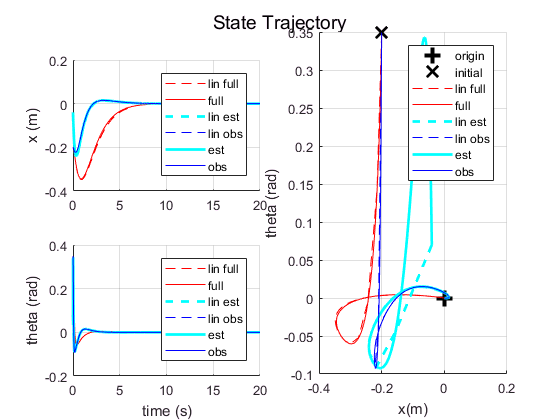

% lin, cl
sys_cl=ss(A-BK,B,C,D);
for i=1:n_test,
    [~,tt,x]=lsim(sys_cl,zeros(size(t)),t,x0(:,i));
    subplot 221;plot(tt,x(:,1),'r--','DisplayName','lin full')
    subplot 223;plot(tt,x(:,2),'r--','DisplayName','lin full')
    subplot 122;plot(x(:,1),x(:,2),'r--','DisplayName','lin full')
end

% non-lin, cl
for i=1:n_test,
    [tt,x] = ode45(@(t,x) odefun(t,x,BK, params), tspan, x0(:,i));
    subplot 221;plot(tt,x(:,1),'r','DisplayName','full')
    subplot 223;plot(tt,x(:,2),'r','DisplayName','full')
    subplot 122;plot(x(:,1),x(:,2),'r','DisplayName','full')
end

% lin, cl + obs
Nbar = 1.0;
At = [A-BK, BK; zeros(size(A)), A-LC];
Bt = [B*Nbar; zeros(size(B))];
Ct = [C, zeros(size(C))];
sys_cl = ss(At, Bt, Ct, 0);
for i=1:n_test,
    [~,tt,xh]=lsim(sys_cl,zeros(size(t)),t,x0_hat(:,i));
    
    x = xh(:,1:4);
    x_err = xh(:,5:8); % err, not est
    x_est = x - x_err;
    
    subplot 221;plot(tt,x_est(:,1),'c--','DisplayName','lin est','linewidth',2)
    subplot 223;plot(tt,x_est(:,2),'c--','DisplayName','lin est','linewidth',2)
    subplot 122;plot(x_est(:,1), x_est(:,2),'c--','DisplayName','lin est','linewidth',2)
    
    subplot 221;plot(tt,x(:,1),'b--','DisplayName','lin obs')
    subplot 223;plot(tt,x(:,2),'b--','DisplayName','lin obs')
    subplot 122;plot(x(:,1),x(:,2),'b--','DisplayName','lin obs')
end

% non-lin, cl + obs
for i=1:n_test,
    [tt,xh] = ode45(@(t,x) odefun2(t,x,BK,LC,params), tspan, x0_hat(:,i));
    x = xh(:,1:4);
    x_err = xh(:,5:8); % err, not est
    x_est = x - x_err;
    subplot 221;plot(tt,x_est(:,1),'c','DisplayName','est','linewidth',2)
    subplot 223;plot(tt,x_est(:,2),'c','DisplayName','est','linewidth',2)
    subplot 122;plot(x_est(:,1), x_est(:,2),'c','DisplayName','est','linewidth',2)
    
    subplot 221;plot(tt,x(:,1),'b','DisplayName','obs')
    subplot 223;plot(tt,x(:,2),'b','DisplayName','obs')
    subplot 122;plot(x(:,1),x(:,2),'b','DisplayName','obs')
end

%post-format figure
subplot 221;hold off;legend('show');grid;ylabel('x (m)')
subplot 223;hold off;legend('show');grid;ylabel('theta (rad)');xlabel('time (s)')
subplot 122;hold off;legend('show');grid;ylabel('theta (rad)');xlabel('x(m)')
suptitle('State Trajectory');

**Extra Plots**

figure;
y = x*K';

y =     9.5800
    9.5800
    9.5800
    9.5800
    9.5800
    9.5800
    9.5799
    9.5799
    9.5799
    9.5799


plot(tt,y);

Error using plot
Vectors must be the same length.

px = x(:,1) .* cos(x(:,2));
py = x(:,1) .* sin(x(:,2));
comet(px,py)
%multicomet

## System State Transition

function fx = f(s, p)
    % s = state, p = parameter
    tmp = num2cell(p);
    [m, M, g, l] = deal(tmp{:});
    
    x = s(1);
    t = s(2);
    v = s(3);
    w = s(4);
    
    ax = -g * sin(t);
    at = -g * m * x * cos(t) / ...
        (l^2*M/12+m*x^2);
    
    fx = [v,w,ax,at]';
end

## ODE v1

function dxdt = odefun(~,x,BK,p)
    dxdt = f(x,p) - BK*x;
end

**ODE v2**

function dxdt = odefun2(~,xh,BK,LC,p)
    %xh
    x=xh(1:4);xe=xh(5:8);
    
    dxdt = [f(x,p);f(x,p)-f(x-xe,p)] + [-BK, BK;zeros(size(BK)), -LC]*[x;xe];
    %+[eye(2) zero(2);eye(2) L]*[d n];
end